# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 50;
KiStatic = 1000;
tdStatic=0.04;

# Toggles

togRMSFreq = 0;
togSinglePoint = 0;
megaSweep = 1;  
figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'FastRestart','off')
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

rat_I = 4.971;


# Set up Data structure

emptyarray = -1000*ones(1,length(pureSinTime));
hybridStruct = struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
    'hError',-1,'hFitSAE',-1,'hSAE',-1);
sweepData = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,...
    'hybridInfo',hybridStruct);

# Parameters

K_P = 10;
K_I = 0;
switch_thresh = inf;
sac_time = 0.04;
n_delay = 0.04;
T_lim_up = inf;
T_lim_low = -inf;

freqindex = 30;

%FFT Params
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   

C_tf = tf([K_P K_I],[1 0]);
[nump,denp]=padeWrap(n_delay);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
den = (1 + num*d_tf);
cl_tf = num/den;

sinin = pureSin(freqindex,:);
%sinout = lsim(cl_tf,sinin,pureSinTime);  
V_in = [pureSinTime' sinin'];
output = sim(simName,'SrcWorkspace','current');
sinout = output.V_out';
sweepData.smoothOut = sinout;
[sweepData.sGain, sweepData.sPhase, sweepData.sError] = ...
    trackingSimHybrid(sinin,sinout,sinfreqs(freqindex),Fs,N);
sweepData.sSAE = sum(abs(sinin-sinout));

sweepData.Kp = K_P;
sweepData.Ki = K_I;
sweepData.inputFreq = sinfreqs(freqindex);

switch_thresh = 2;
sinin = pureSin(freqindex,:);
V_in = [pureSinTime' sinin'];
output = sim(simName,'SrcWorkspace','current');

out = output.V_out';
[sinout,rsquare] = sineFitMod(out,pureSinTime,sinfreqs(freqindex));
sweepData.hybridInfo.hybridOut = out;
sweepData.hybridInfo.switchThresh = switch_thresh;
sweepData.hybridInfo.rsquare = rsquare;
sweepData.hybridInfo.hFit = sinout;
[sweepData.hybridInfo.hGain, sweepData.hybridInfo.hPhase,...
    sweepData.hybridInfo.hError] = trackingSimHybrid(sinin,sinout,sinfreqs(freqindex),Fs,N);
sweepData.hybridInfo.hFitSAE = sum(abs(sinin-sinout));
sweepData.hybridInfo.hSAE = sum(abs(sinin-out));
figure
quickplot(sweepData,K_I,K_P,switch_thresh,sinfreqs(freqindex),pureSinTime,K_P,K_I,switch_thresh,sinfreqs(freqindex),0)

ans = 1

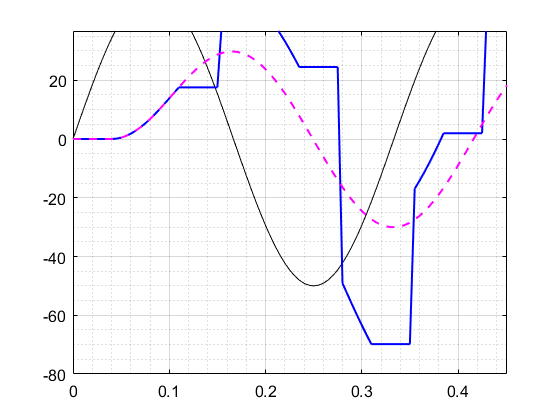

xlim([0 1])